clear all 
clc

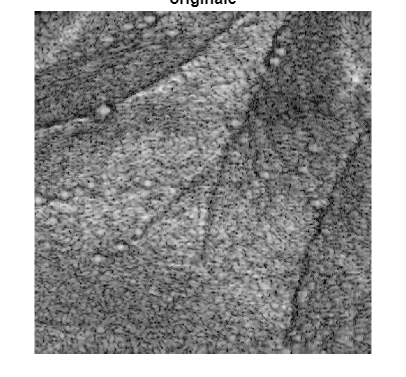

im = fullfile("imageGeneratedFrom3D/Luongo_1_rimozioneRes_000/immagine_1_0.0924.jpg");
I = imread(im);
originale = I;
imshow(I);title('originale');figure;

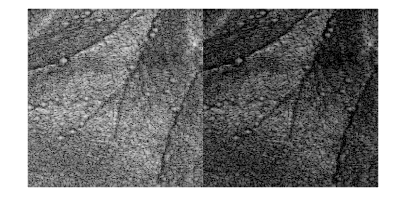

istogramma = imhist(I);
[value, idx] = max(istogramma);
centralValue = size(istogramma,1)/4 - idx;
K = I+centralValue;
montage({I K})

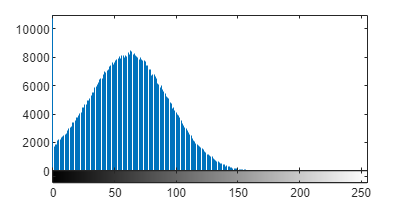

imhist(K);

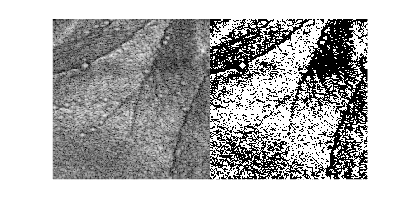

J = histeq(K, [220 255]);
imshowpair(I,J,'montage')
axis off

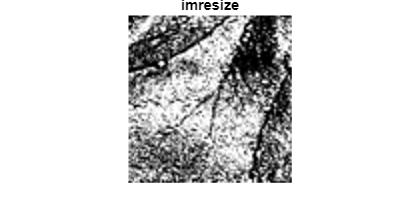

%RESIZE DELL'IMMAGINE
im1=imresize(J, 0.1, 'bicubic'); % imposto la grandezza dell'immagine mantenendo le proporzioni
im1=imresize(im1, 2, 'bicubic');
imshow(im1);title('imresize');figure;

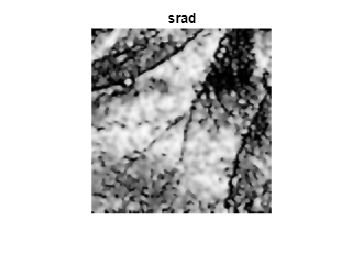

%APPLICAZIONE FILTRO SRAD
[filteredImage] = specklefilt(im1);
imshow(filteredImage);title('srad');figure;

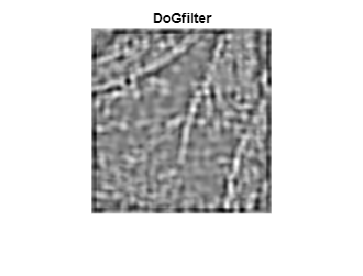

%APPLICAZIONE FILTRO DoG
gaussian1 = fspecial('gaussian',11,15); 
gaussian2 = fspecial('gaussian',11,20);
gaussian = gaussian2 - gaussian1;
dogFilterImage2 = conv2(double(filteredImage), gaussian, 'same');
imshow(dogFilterImage2,[]);title('DoGfilter');figure;

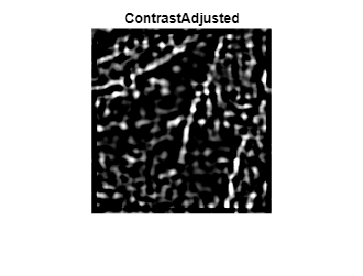

%AUMENTO CONTRASTO
contrastAdjusted = imadjust(dogFilterImage2,stretchlim(dogFilterImage2),[]);
imshow(contrastAdjusted); title('ContrastAdjusted'); figure;

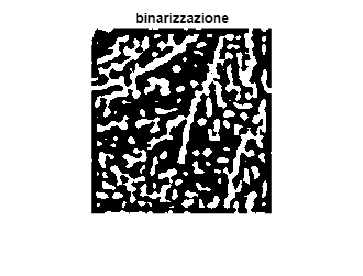

%BINARIZZAZIONE
A = contrastAdjusted;
meanValue=mean2(A);
threshold = meanValue*1; %più è alto il fattore di scala meno dettagli saranno presenti

A_bw = A > threshold;
imshow(A_bw); title('binarizzazione'); figure;

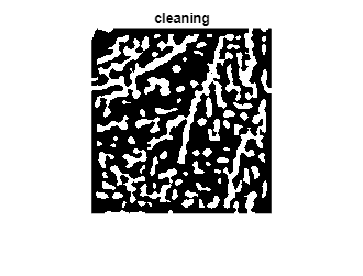

%CLEANING
CC= bwconncomp(A_bw);
S = regionprops(CC, 'Area');
L = labelmatrix(CC);  
BW2 = ismember(L, find([S.Area] >= 10));
imshow(BW2); title('cleaning'); figure;

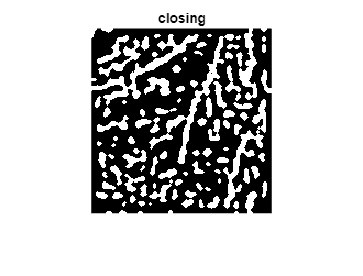

%CLOSING
se=strel('disk',1);
closing=imopen(BW2, se);
imshow(closing); title('closing'); figure;

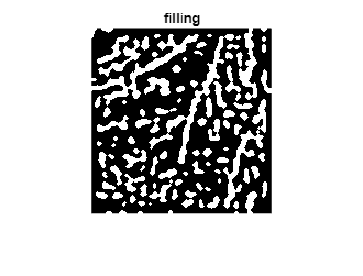

%FILLING
filling= imfill(closing,'holes');
imshow(filling);title('filling');figure;

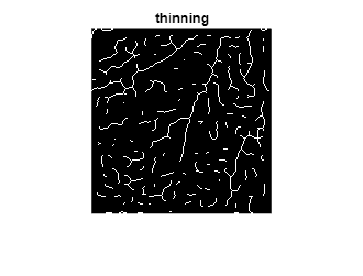

%THINNING
thinning= bwmorph(filling, 'thin', inf);
imshow(thinning);title('thinning');figure;

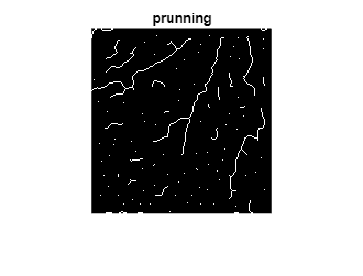

%PRUNNING
prun= bwmorph( thinning, 'spur', 6);
imshow(prun);title('prunning');figure;

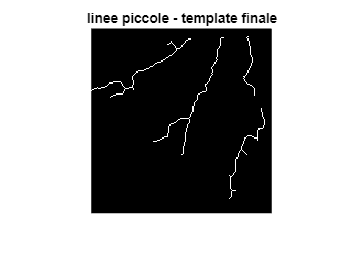

%CLEANING LINEE PICCOLE
BWz = bwareaopen(prun, 40);
imshow(BWz);title('linee piccole - template finale');figure;

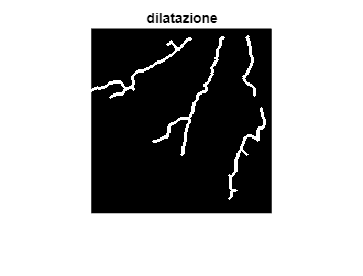

%DILATAZIONE WARING RIMETTERE COME PRIMA DISK 6
dilatation_mask= strel('disk', 1);
dilatedImageDat= imdilate(BWz, dilatation_mask);
imshow(dilatedImageDat); title('dilatazione'); figure;

originale = imresize(originale, 0.2, 'bicubic');
rgbImage = cat(3, originale, originale, originale);

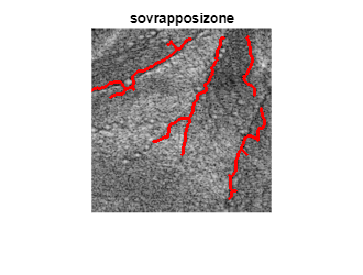


%SOVRAPPOSIZIONE %%WARNING:RIMETTERE COME PRIMA
clear m n1

[m n1]= size(originale);% prima era size(I)
 for i=1 : m
    for j=1 : n1
        if  dilatedImageDat(i,j)==1
        %inputImage(i,j)=255;
        rgbImage(i,j,1)=255;
        rgbImage(i,j,2)=0;
        rgbImage(i,j,3)=0;
        end 
    end 
 end	 


imshow(rgbImage);title('sovrapposizone'); figure;